load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\data_frame.mat')

idx=0;
allsubj=0;
for studyrank=1:height(df) %stats
        if ~isempty(df.GIV_stats_rating(studyrank).delta) && df.anticipismodeled(studyrank) && ~isempty(df.putamensctivation{studyrank}) %%~isempty(stats(studyrank).pla)% necessary as "sum" returns 0 for [] for some stupid reason
            idx=idx+1;
            % collecting study wise metainfo
            nsubj=sum(~isnan((df.GIV_stats_rating(studyrank).delta)));
            studysubj(idx)=nsubj;
            allsubj=allsubj+nsubj;
            allstudyrank(idx)=studyrank;
            putplacact_x=df.putamensctivation{studyrank}; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script.

%             signatureresponse_m=df.pain_placebo_minus_control{studyrank,1}.NPS;
            signatureresponse_m=df.pain_placebo_minus_control{studyrank,1}.siips;
            rating_behav_y=df.GIV_stats_rating(studyrank).delta;%(~ex_subj,:); %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script.
        
            %update: the previous rating difference represented
            %placebo-control--> change to control-placebo so higher vlaues
            %would mean higher behavior analgesi
            rating_behav_y=-rating_behav_y;

            mod1=fitlm(putplacact_x,signatureresponse_m);
            a_est=mod1.Coefficients("x1",:).Estimate;
            a_est_se=mod1.Coefficients("x1",:).SE;
        
            mod2=fitlm(horzcat(putplacact_x,signatureresponse_m),rating_behav_y);
            b_est=mod2.Coefficients("x2",:).Estimate;
            b_est_se=mod2.Coefficients("x2",:).SE;

            all_a_est(idx)=a_est;
            all_b_est(idx)=b_est;
               varratio=(sqrt(a_est_se)./sqrt(b_est_se));
                ab_stand(idx)=a_est.*b_est.*varratio;

                se_ab=sqrt(((a_est.^2).*(b_est_se.^2))+((b_est.^2).*(a_est_se.^2)));
                se_ab_aroian=sqrt(((a_est.^2).*(b_est_se.^2))+((b_est.^2).*(a_est_se.^2))+(a_est_se.^2).*(b_est_se.^2));
                se_stand_sobel(idx)=varratio.*se_ab;
                z_ab_sobel(idx)=(a_est.*b_est)./se_ab;
                z_ab_Aroian(idx)=(a_est.*b_est)./se_ab_aroian;
                ab_weight(idx)=sqrt(nsubj);

        end
end

sum(z_ab_sobel.*ab_weight)/sqrt(sum(studysubj.^2))

ans = 0.4430

allwight=ab_weight./sqrt(sum(studysubj.^2))

allwight =     0.0315    0.0315    0.0339    0.0280    0.0457    0.0457    0.0402    0.0408    0.0395    0.0354    0.0346    0.0445    0.0375    0.0621    0.0395    0.0354    0.0445


sum(allwight)

ans = 0.6701

sqrt(sum(studysubj.^2))

ans = 138.5280

ab_weight;
sqrt(40/526);
sum(ab_weight./sqrt(allsubj));
z_ab_sobel;
se_stand_sobel

se_stand_sobel =     1.1586    0.5103    8.1024    1.4195    0.4785   10.0733  124.9033    5.2238   43.1046  126.1052    2.0883    0.4070    7.6237  134.1398    8.2459   10.0553    0.4176


z_ab_Aroian;
allstudyrank;

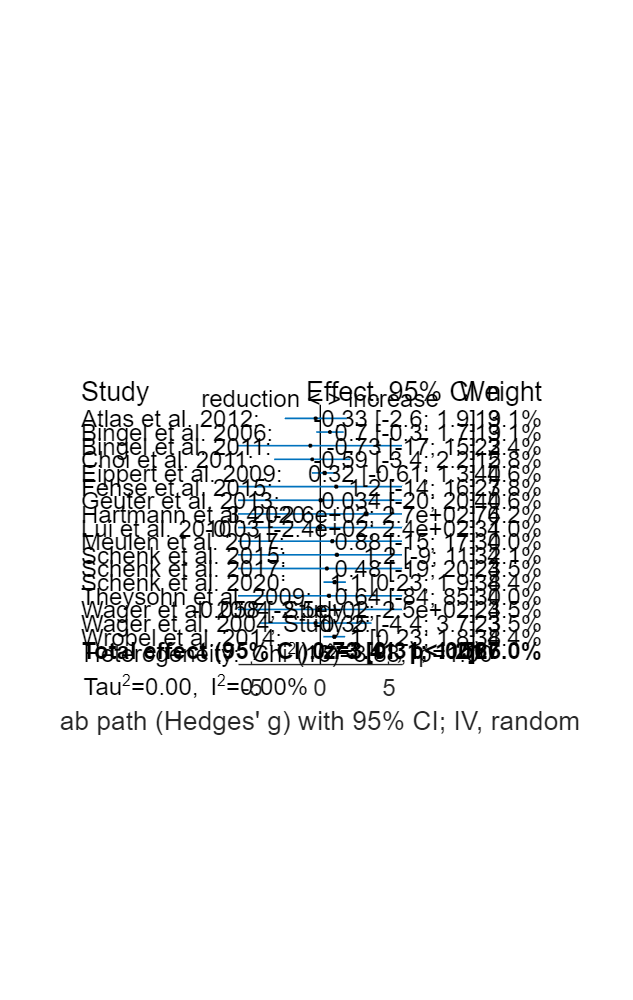

figure('Position',[100, 100, 2400, 1200]);
forest_plot_mediation_BK(z_ab_sobel,se_stand_sobel,studysubj,...
    allwight,...
            summ_ab,... 
            'study_ID_texts',df.study_citations(allstudyrank),... %must rule out the Koban study here...
                  'outcome_labels',['ab path',' (Hedges'' g)'],...
                  'type','random',...
                  'summary_stat','g',...
                  'with_outlier',0,... %'WI_subdata',{GIV_stats.std_delta},...
                  'box_scaling',1,...
                  'text_offset',0,...
                  'X_scale',6);


% varnames={'rating'};
% %           'NPS'};
% nicevarnames={'Pain ratings'};%,...
% %               'NPS response'};
% summary=[];
% for i = 1:numel(varnames)
%     dataforplotting=[df.(['GIV_stats_',varnames{i}])];
%     dataforplotting=dataforplotting(~isnan(vertcat(dataforplotting(:).mu)));
%     summary.(varnames{i})=forest_plotter(dataforplotting,...
%                   'study_ID_texts',df.study_citations(1:25),... %must rule out the Koban study here...
%                   'outcome_labels',[nicevarnames{i},' (Hedges'' g)'],...
%                   'type','random',...
%                   'summary_stat','g',...
%                   'with_outlier',0,... %'WI_subdata',{GIV_stats.std_delta},...
%                   'box_scaling',1,...
%                   'text_offset',0,...
%                   'X_scale',2);

%calculate the summary score of the abpath
%for NPS
[summ_ab.fixed,...
 summ_ab.random,...
 summ_ab.heterogeneity]=GIV_weight_BK(z_ab_sobel',se_stand_sobel');
summ_ab.fixed.p

ans = 0.9914

summ_ab.random.p

ans = 0.9914

         
         %%

%calculate the summary score of the abpath
%for SIIPS
[summ_ab.fixed,...
 summ_ab.random,...
 summ_ab.heterogeneity]=GIV_weight_BK(ab_stand',se_stand_sobel');
summ_ab.fixed.p

ans = 0.1473

summ_ab.random.p

ans = 0.2375

This part aims to check the correlation between brain signature and the pain rating.

load('C:\Users\lenov\Documents\PICO_DATA\originaldatastructure\intermediatefiles\data_frame.mat')

idx=0;
allsubj=0;
for studyrank=1:height(df) %stats
        if ~isempty(df.GIV_stats_rating(studyrank).delta) && df.anticipismodeled(studyrank) && ~isempty(df.putamensctivation{studyrank}) %%~isempty(stats(studyrank).pla)% necessary as "sum" returns 0 for [] for some stupid reason
            idx=idx+1;
            % collecting study wise metainfo
            disp(df.study_ID(studyrank))
            nsubj=sum(~isnan((df.GIV_stats_rating(studyrank).delta)));
            studysubj(idx)=nsubj;
            allsubj=allsubj+nsubj;
            allstudyrank(idx)=studyrank;
            putplacact_x=df.putamensctivation{studyrank}; %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script.

%             signatureresponse_m=df.pain_placebo_minus_control{studyrank,1}.NPS;
            signatureresponse_m=df.pain_placebo_minus_control{studyrank,1}.siips;
%             rating_behav_y=df.GIV_stats_rating(studyrank).delta;%(~ex_subj,:); %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script.
            rating_behav_y=df.GIV_stats_rating101(studyrank).delta;%(~ex_subj,:); %this is placebo-control delta, as it was the order in the summary_within arguments in the A_meta_analysis_placebo_all_BK script.
            


            

            mod1=fitlm(putplacact_x,signatureresponse_m); %fitlm(X,Y)            
            a_est=mod1.Coefficients("x1",:).Estimate;
            a_est_se=mod1.Coefficients("x1",:).SE;
            mod2=fitlm(horzcat(putplacact_x,signatureresponse_m),rating_behav_y);
            b_est=mod2.Coefficients("x2",:).Estimate;
            b_est_se=mod2.Coefficients("x2",:).SE;
            
%             mod1_rf=robustfit(putplacact_x,signatureresponse_m); %fitlm(X,Y)
%             a_est=mod1_rf(2);
%             mod2_rf=robustfit(horzcat(putplacact_x,signatureresponse_m),rating_behav_y);
%             b_est=mod2_rf(3);
            

            fprintf('The mediation effect is: %.4f',a_est*b_est)
            
            mydist=bootstrapmediation(putplacact_x,rating_behav_y,signatureresponse_m);
%             all_a_est(idx)=a_est;
%             all_b_est(idx)=b_est;
%                varratio=(sqrt(a_est_se)./sqrt(b_est_se));
%                 ab_stand(idx)=a_est.*b_est.*varratio;
% 
%                 se_ab=sqrt(((a_est.^2).*(b_est_se.^2))+((b_est.^2).*(a_est_se.^2)));
%                 se_ab_aroian=sqrt(((a_est.^2).*(b_est_se.^2))+((b_est.^2).*(a_est_se.^2))+(a_est_se.^2).*(b_est_se.^2));
%                 se_stand_sobel(idx)=varratio.*se_ab;
%                 z_ab_sobel(idx)=(a_est.*b_est)./se_ab;
%                 z_ab_Aroian(idx)=(a_est.*b_est)./se_ab_aroian;
%                 ab_weight(idx)=sqrt(nsubj);

        end
end

    {'atlas'}



The mediation effect is: -0.8174

    {'bingel06'}



The mediation effect is: -2.4957

    {'bingel11'}



The mediation effect is: -0.9484

    {'choi'}



The mediation effect is: -0.0045

    {'eippert'}



The mediation effect is: 0.0982

    {'geuter'}



The mediation effect is: 0.1292

    {'lui'}



The mediation effect is: 0.1124

    {'schenk'}



The mediation effect is: 1.3044

    {'theysohn'}



The mediation effect is: -6.6960

    {'wager04a_princeton'}



The mediation effect is: -12.9924

    {'wager04b_michigan'}



The mediation effect is: 0.5359

    {'wrobel'}



The mediation effect is: -0.0209

    {'fehse'}



The mediation effect is: 0.6380

    {'hartmann'}



The mediation effect is: 19.9228

Mean mediation effect: 20.3005
95% CI: [2.7485, 44.6479]


    {'meulen'}



The mediation effect is: -0.2321

    {'schenk17'}



The mediation effect is: 1.7554

    {'schenk20'}



The mediation effect is: 0.0042

function [distr] = bootstrapmediation(X,Y,M,varargin)

    p = inputParser;  % Create input parser
    addRequired(p, 'X'); % Add required input %maybe specify type
    addRequired(p, 'Y'); % Add required input %maybe specify type
    addRequired(p, 'M'); % Add required input %maybe specify type
    numBootstraps = 1000;  % Default value for input2
    addOptional(p, 'nboot', numBootstraps); % Add optional input with default value
    addOptional(p, 'robust', 'off', @ischar);
    parse(p, X,Y,M, varargin{:}); % Parse inputs
    x = p.Results.X;
    y = p.Results.Y;
    m = p.Results.M;

    mynboot = p.Results.nboot;
    myrobust = p.Results.robust;

    
    % Preallocate arrays to store bootstrap mediation estimates
    bootstrap_estimates = zeros(mynboot, 1);
    
    % Loop over the number of bootstrap samples
    for i = 1:mynboot
        % Resample indices with replacement
        resampleIndices = randsample(length(y), length(y), true);
        
        % Create resampled datasets
        x_resampled = x(resampleIndices,:);
        m_resampled = m(resampleIndices);
        y_resampled = y(resampleIndices);
        if strcmp(myrobust,'on')
            mod1_resampled = robustfit(x_resampled, m_resampled);
            a_est_resampled = mod1_resampled(2);
            
            mod2_resampled = robustfit(horzcat(x_resampled, m_resampled), y_resampled);
            b_est_resampled = mod2_resampled(3);
        else
                
            % Fit the models on the resampled data
            mod1_resampled = fitlm(x_resampled, m_resampled);
            a_est_resampled = mod1_resampled.Coefficients("x1",:).Estimate;
            
            mod2_resampled = fitlm(horzcat(x_resampled, m_resampled), y_resampled);
            b_est_resampled = mod2_resampled.Coefficients("x2",:).Estimate;
        end    
        % Calculate the mediation estimate
        bootstrap_estimates(i) = a_est_resampled * b_est_resampled;
    end
    
    % Calculate the mean and confidence interval of the bootstrap estimates
    mediationEffect_mean = mean(bootstrap_estimates);
    mediationEffect_ci = quantile(bootstrap_estimates, [0.025 0.975]); % 95% CI
    
    % Display results
    if (mediationEffect_ci(1)<0) && (0<mediationEffect_ci(2))
        warning('the bootstrappins resulted in non-signficant mediation effect')
    else
        fprintf('Mean mediation effect: %.4f\n', mediationEffect_mean);
        fprintf('95%% CI: [%.4f, %.4f]\n', mediationEffect_ci(1), mediationEffect_ci(2));
    end

    distr = struct('mean',mediationEffect_mean,'ci',mediationEffect_ci);
end